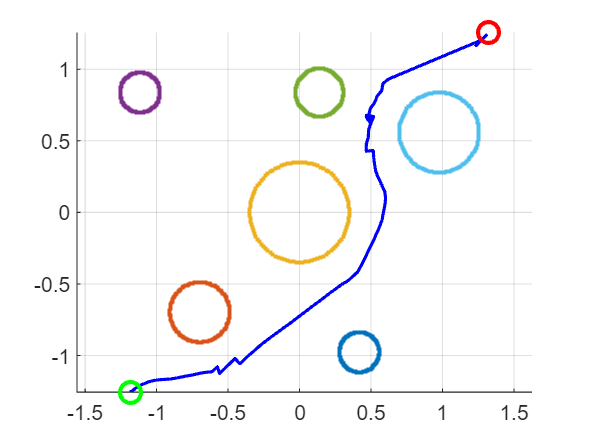

% Campo Potencial Artificial con Predicción de Desviación y Simulación Pure Pursuit
clc; clear; close all;

% === Posiciones inicial y final ===
pos_init = [-1.1858, -1.2555, deg2rad(30)];
pos_fin = [1.3253, 1.2555];

% === Parámetros de obstáculos ===
k = 1.395;
CC = k * 0.1 * [3 -7; -5 -5; 0 0; -8 6; 1 6; 7 4]; % centros
RC = k * 0.1 * [1 1.5 2.5 1 1.2 2];               % radios
N = 100;
obstacle_points = cell(length(RC), 1);
for i = 1:length(RC)
    obstacle_points{i} = generate_obs(CC(i,:), RC(i), N);
end

% === Parámetros del algoritmo ===
Katt = 3.00;
Krep = 1;
rho_0 = 0.2;
d = 0.05;
step_size = 0.05;
thresh = 0.05;
max_iter = 5000;
N_pred = 20;

% === Inicialización ===
x = pos_init(1:2);
theta = pos_init(3);
x_goal = pos_fin;
path = [x, theta];

% === Algoritmo de predicción con desviación perpendicular ===
for iter = 1:max_iter
    x_temp = x;
    pred_path = x_temp;
    for j = 1:N_pred
        F_att = attractive_force(x_temp, x_goal, d, Katt);
        F_rep = repulsive_force(x_temp, obstacle_points, rho_0, Krep);
        F_total = F_att + F_rep;
        x_temp = x_temp - step_size * F_total / (norm(F_total) + 1e-10);
        pred_path = [pred_path; x_temp];
    end

    dists = zeros(size(pred_path,1),1);
    for k = 1:length(dists)
        dists(k) = perp_distance(x, x_goal, pred_path(k,:));
    end

    [~, idx_max] = max(dists);
    temp_goal = pred_path(idx_max,:);

    F_att = attractive_force(x, temp_goal, d, Katt);
    F_rep = repulsive_force(x, obstacle_points, rho_0, Krep);
    F_total = F_att + F_rep;
    theta = atan2(F_total(2), F_total(1));
    x = x - step_size * F_total / (norm(F_total) + 1e-10);

    path = [path; x, theta];
    if norm(x - x_goal) <= thresh
        break;
    end
end

% === Visualización de trayectoria ===
figure; hold on; axis equal; grid on;
obstacle_points = cell(length(RC), 1);
for i = 1:length(RC)
    obstacle_points{i} = generate_obs(CC(i,:), RC(i), 100);
    plot(obstacle_points{i}(:,1), obstacle_points{i}(:,2), '.', 'DisplayName', sprintf('Círculo %d', i));
end
plot(path(:,1), path(:,2), 'b-', 'LineWidth', 1.5);
plot(x_goal(1), x_goal(2), 'ro', 'MarkerSize', 10, 'LineWidth',2);
plot(path(1,1), path(1,2), 'go', 'MarkerSize',10, 'LineWidth', 2);

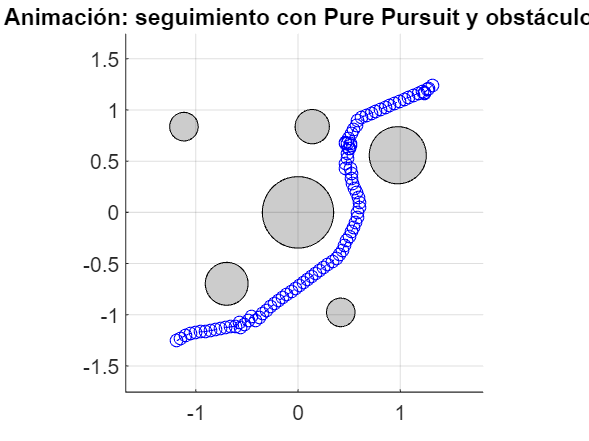


% === Simulación con controllerPurePursuit ===
controller = controllerPurePursuit;
release(controller);
controller.Waypoints = path(:,1:2);
controller.DesiredLinearVelocity = 0.2;
controller.MaxAngularVelocity = 1.0;
controller.LookaheadDistance = 0.3;

robotInitialLocation = path(1,1:2);
robotGoal = path(end,1:2);
initialOrientation = path(1,3);
robotCurrentPose = [robotInitialLocation, initialOrientation]';
goalRadius = 0.05;
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);
robot.TrackWidth = 0.3;
frameSize = robot.TrackWidth / 0.8;

figure;
axis equal; grid on;
xlim([min(path(:,1))-0.5, max(path(:,1))+0.5]);
ylim([min(path(:,2))-0.5, max(path(:,2))+0.5]);
title('Animación: seguimiento con Pure Pursuit y obstáculos');
hold on;

% Obstáculos
theta_circ = linspace(0, 2*pi, 100);
for i = 1:length(RC)
    xc = CC(i,1) + RC(i)*cos(theta_circ);
    yc = CC(i,2) + RC(i)*sin(theta_circ);
    fill(xc, yc, 'k', 'FaceAlpha', 0.2);
end

% Trayectoria
plot(path(:,1), path(:,2), 'b--o', 'DisplayName', 'Trayectoria APF');

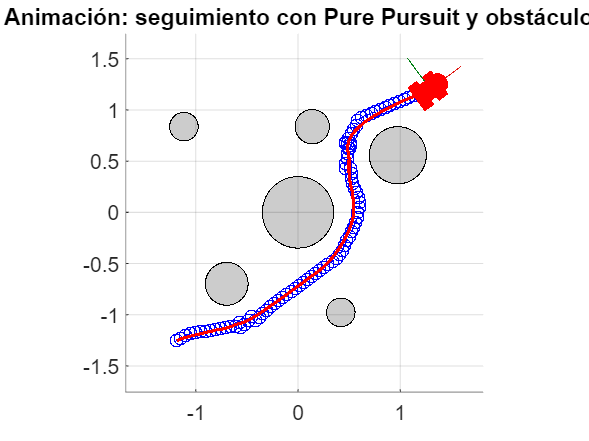


% Bucle de simulación
distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
poses = robotCurrentPose';

while distanceToGoal > goalRadius
    [v, omega] = controller(robotCurrentPose);
    vel = [v * cos(robotCurrentPose(3));
           v * sin(robotCurrentPose(3));
           omega];
    robotCurrentPose = robotCurrentPose + vel * sampleTime;
    poses = [poses; robotCurrentPose'];

    cla;
    for i = 1:length(RC)
        xc = CC(i,1) + RC(i)*cos(theta_circ);
        yc = CC(i,2) + RC(i)*sin(theta_circ);
        fill(xc, yc, 'k', 'FaceAlpha', 0.2);
    end
    plot(path(:,1), path(:,2), 'b--o');

    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    try
        plotTransforms(plotTrVec', plotRot, MeshFilePath="groundvehicle.stl", Parent=gca, View="2D", FrameSize=frameSize);
    catch
        quiver(robotCurrentPose(1), robotCurrentPose(2), cos(robotCurrentPose(3))*0.2, sin(robotCurrentPose(3))*0.2, 'r', 'LineWidth', 2);
    end
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    waitfor(vizRate);
end

plot(poses(:,1), poses(:,2), 'r-', 'LineWidth', 1.5);